# Simulink basics

LECTURE 04/11 FROM VIDEO LECTURES (DRIVE)

Given the system (C and G) simulate the system, when r is a unitary step function

(Note I didn't copy exercise text, just trust C and G below :) )

close all
clear
clc

s = tf('s');
Ts = 1e-3;
z = tf('z', Ts);

G_ct = 2122.4/(s*(s+59.24));
C = 15.581*(z-0.9425)/(z-0.8028);

-> C and G_ct are LTI system blocks from Control System Toolbox

-> LTI system block is able to simulate both CT and DT systems. It is able to modify its behaviour in order to simulate both the typologies

-> Between C and G_ct we need a D->A converter (ZOH)

-> It's important to set correctly the sample time in the ZOH filter

-> r (step) configuration: step time = 0; final value = 1 (unitary step)

-> To collect data I use "to workspace" box

-> Before simulating, I open the "model configuration parameters (with double click) and inside of solver details I need to set some variables:

    1) max step size: [1/100-1/1000]*Ts

    2) min step size: 1/10 * (max step size)

-> Now I have to set some parameters to the "to workspace" blocks, because we have some signal in DT and other in CT -> to workspace blocks must collect signals at different speed values

Sample time for CT signals can be set to Ts*0.001, in this case we are collecting 1000 points for every sampling time

For DT signal we leave the sample time = Ts (because we have the signal info only every Ts seconds)

The last thing that we have to set is the simulation and time: I set Tend as stop time 

Tend = 0.2; 
% I can start with a guess and then at the end modify the value accordingly
% to the simulation (EDIT: after the plot I can see that the transient at
% 0.2 is finished => 0.2 is fine)

Now I can run the simulation!!!!

sim = sim("sim_unitary_step.slx");

At this point, I can plot my signals

Before, let unpack signals from simulation

y = sim.y;
r = sim.r;
e = sim.e;
u = sim.u;
u_sampled = sim.u_sampled;

And now I can plot them

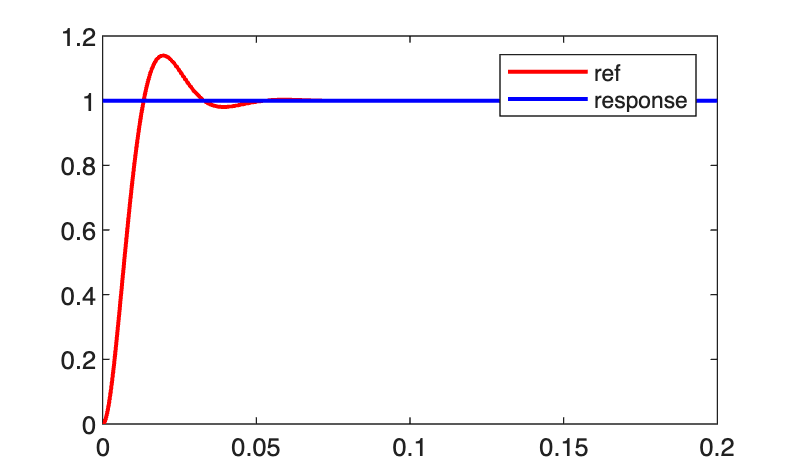

figure(1); title("plot of the response y and the refence r");
plot(y.time, y.data, 'r',"LineWidth",1.5)
hold on
plot(r.time, r.data, 'b', "LineWidth",1.5)
legend("response", "ref")

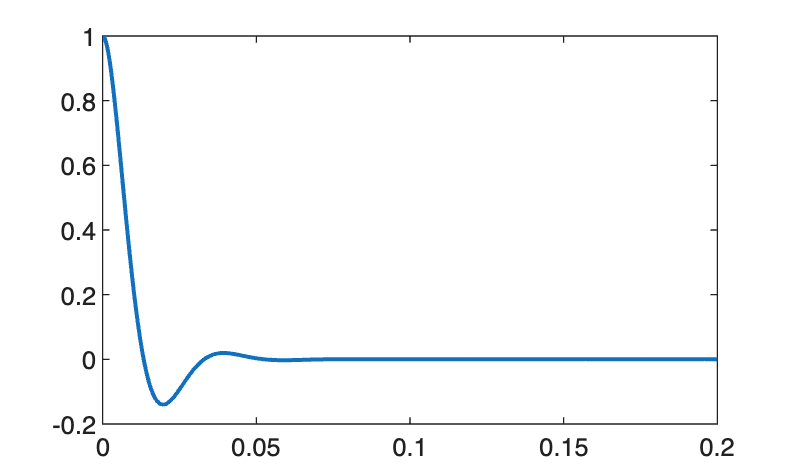


figure(2); title("error")
plot(e.time, e.data, "LineWidth",1.5);

We can also plot the control input u, both sample one and CT one

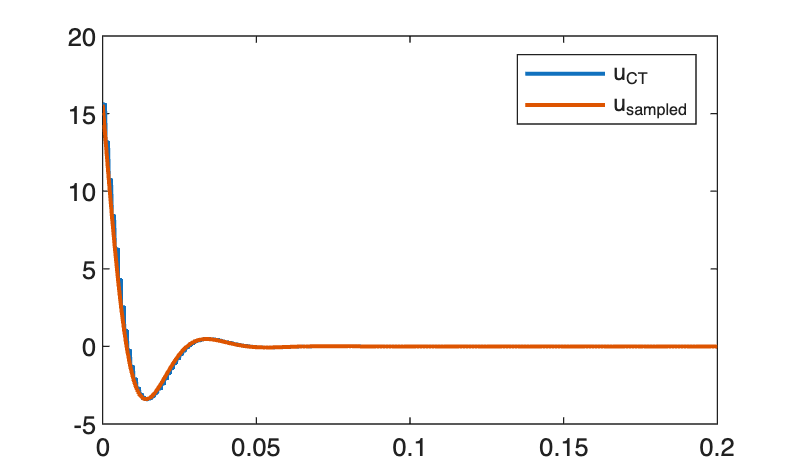

figure(3); title("u vs u_{sampled} (first picture)")
plot(u.time, u.data, "LineWidth",1.5);
hold on
plot(u_sampled.time, u_sampled.data, "LineWidth",1.5)
legend("u_{CT}", "u_{sampled}")

If we zoom in the figure, we see this

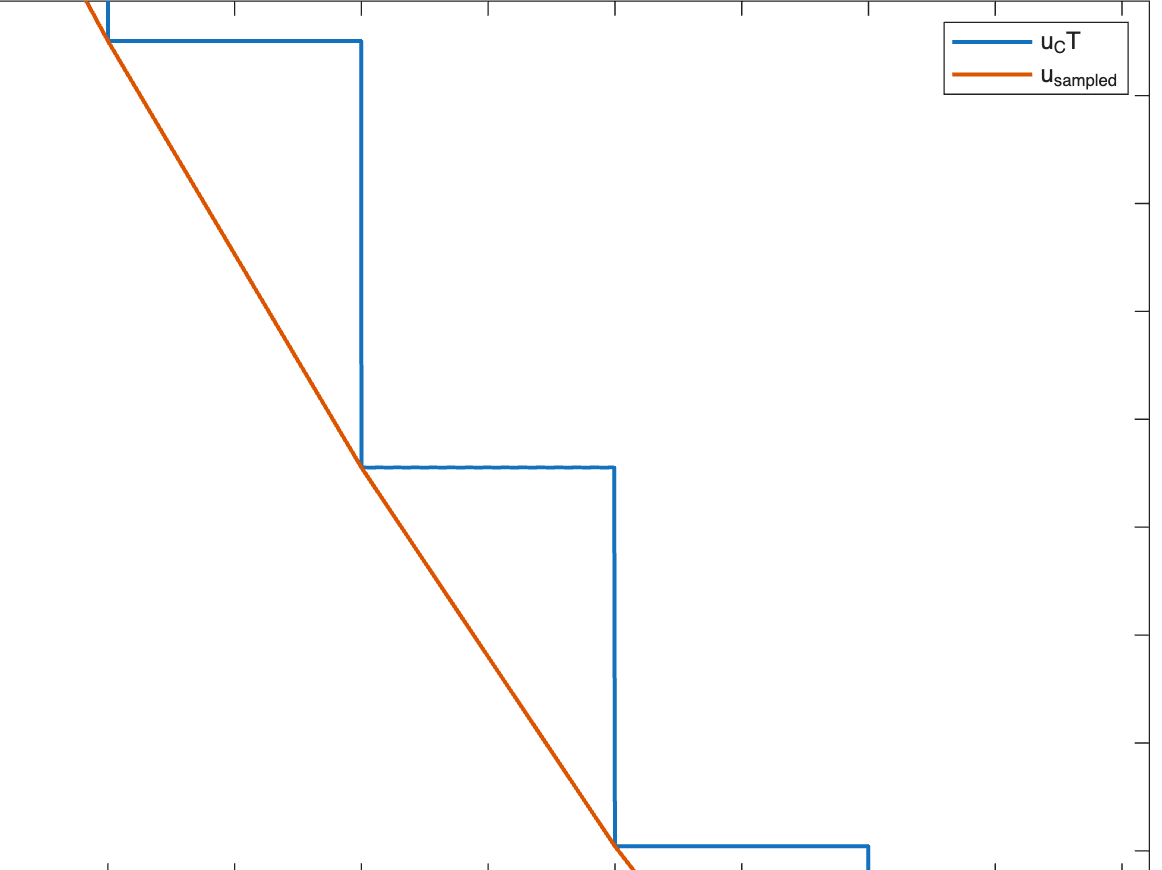

In particular, we observe that u_sampled is plotted by matlab as a continuous signal. That's because matlab simply takes samples and combine them. But we know that this is not correct, since our u_sample is discrete. So, we should write:

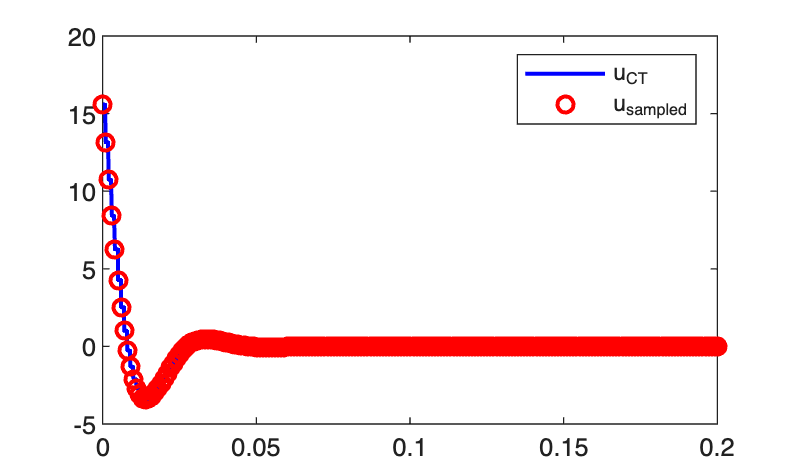

figure(4); title("u vs u_{sampled} (with correct def of u_sampled)")
plot(u.time, u.data, 'b',"LineWidth",1.5);
hold on
plot(u_sampled.time, u_sampled.data, 'ro',"LineWidth",1.5)
legend("u_{CT}", "u_{sampled}")

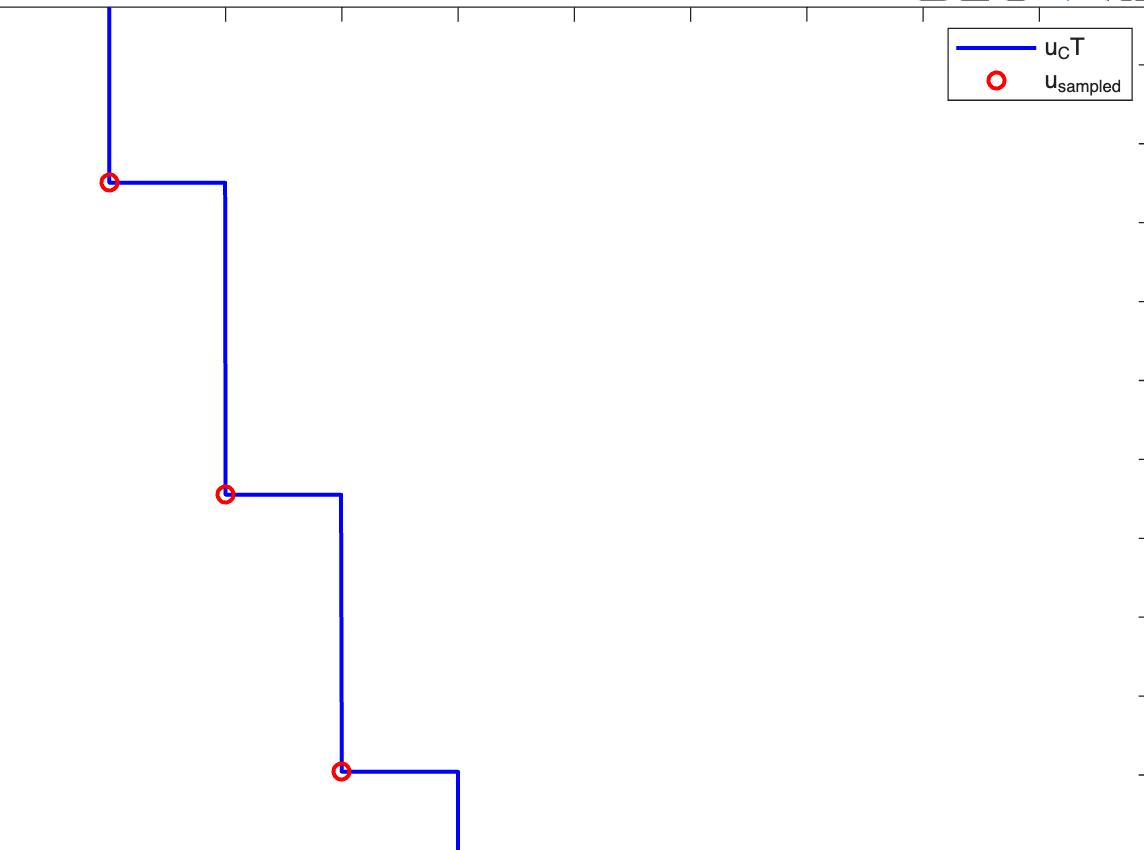

We have now obtained the correct plot of these signals

### Requirements evaluation

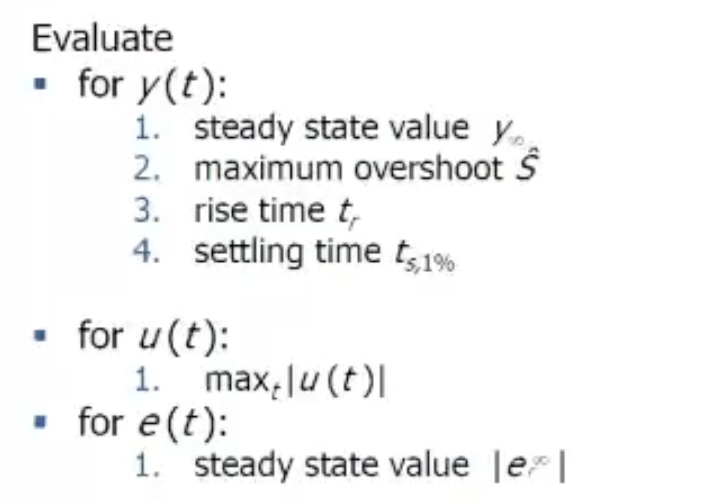

(just see plots)

Setting time -> defined wrt an alfa ("precision"), is the time when the signal enter in the zone (y_inf-alfa, y_inf+alfa) and remains in that zone

max(u) is for t=0

e_inf is 0 for t->inf (NB is an asymptotical behaviour)

#### Save command

Useful to save workspace variables that can be reloaded in a second time.

Sintax: save "..."

To restore the workspace (saved in a .mat file), I do load "..."

I can both save both all the workspace and the single variables, in this second case I'll do: save var1 var2....